# Processing

## Extract point cloud


filename = "All3_540.bag";
%filename = "flat540.bag";
%filename = "150_all_start_2021-10-12-14-24-01.bag";
%filename = '50_all_start_2021-10-12-14-38-49.bag';
%filename ="100_all_start_2021-10-12-14-29-56.bag";
bag = rosbag(filename);
bSel = select(bag,'Topic','/velodyne_packets');

msgStructs = readMessages(bSel,'DataFormat','struct');

msgStructs{1};
veloReader = velodyneROSMessageReader(msgStructs,"VLP16")

veloReader =   velodyneROSMessageReader with properties:

    VelodyneMessages: {23×1 cell}
         DeviceModel: 'VLP16'
     CalibrationFile: 'C:\Program Files\MATLAB\R2021a\toolbox\shared\pointclouds\utilities\velodyneFileReaderConfiguration\VLP16.xml'
      NumberOfFrames: 22
            Duration: 2.198 sec
           StartTime: 2544.6 sec
             EndTime: 2546.8 sec
          Timestamps: [1×22 duration]
         CurrentTime: 2544.6 sec


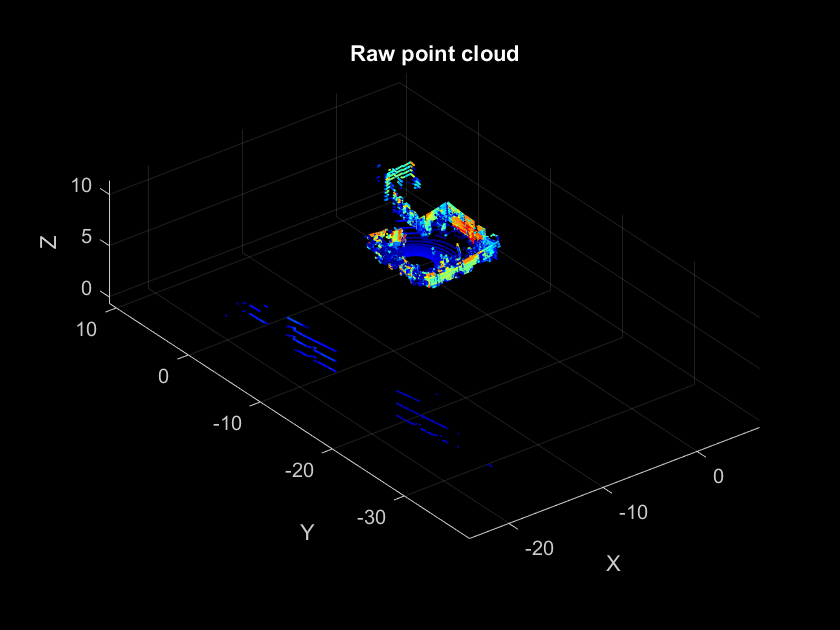

timeDuration = veloReader.StartTime + duration(0,0,1,'Format','s');
ptCloudObj = readFrame(veloReader,timeDuration);
ptCloudLoc = ptCloudObj.Location;
reset(veloReader);

xlimits = [-1.5 -0.5];
ylimits = [-0.5 0.5];
zlimits = [-1 1];

xwide = [-2.5 0];
ywide = [-0.5 0.5];
zwide = [-0.75 0.75];
figure
pcshow(ptCloudObj);
xlabel("X");
ylabel("Y");
zlabel("Z");
title("Raw point cloud")

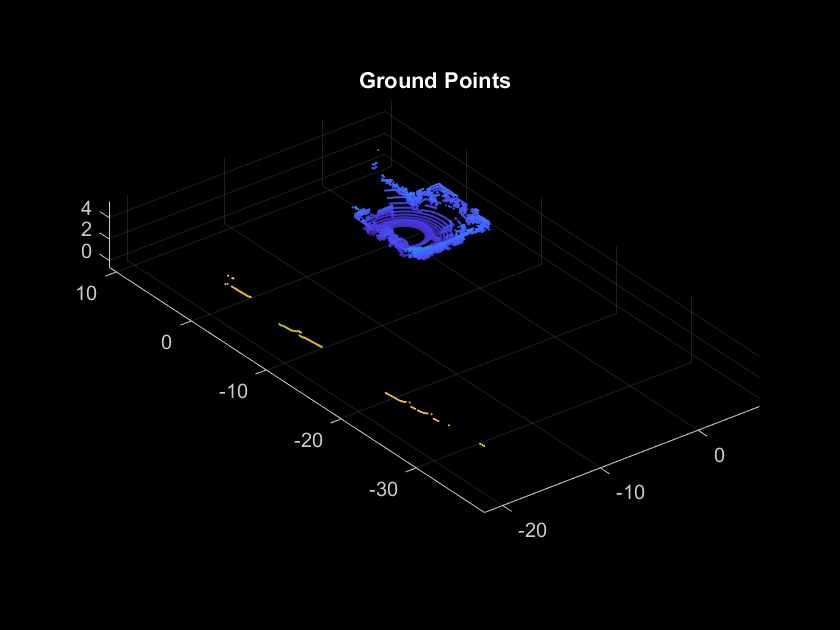


groundPtsIdx = segmentGroundSMRF(ptCloudObj);
ptCloudWithGround = select(ptCloudObj,groundPtsIdx);
figure
pcshow(ptCloudWithGround.Location)
title("Ground Points")

%surf(ptCloudLoc(1), ptCloudLoc(2),ptCloudLoc(3));
%mesh(ptCloudObj)

## Display

%player = pcplayer(xlimits,ylimits,zlimits);
player = pcplayer(xwide,ywide,zwide);
ptCloudDenoise = pcdenoise(ptCloudObj);
while isOpen(player)
    view(player,ptCloudDenoise.Location,ptCloudDenoise.Intensity);
end

## Crop

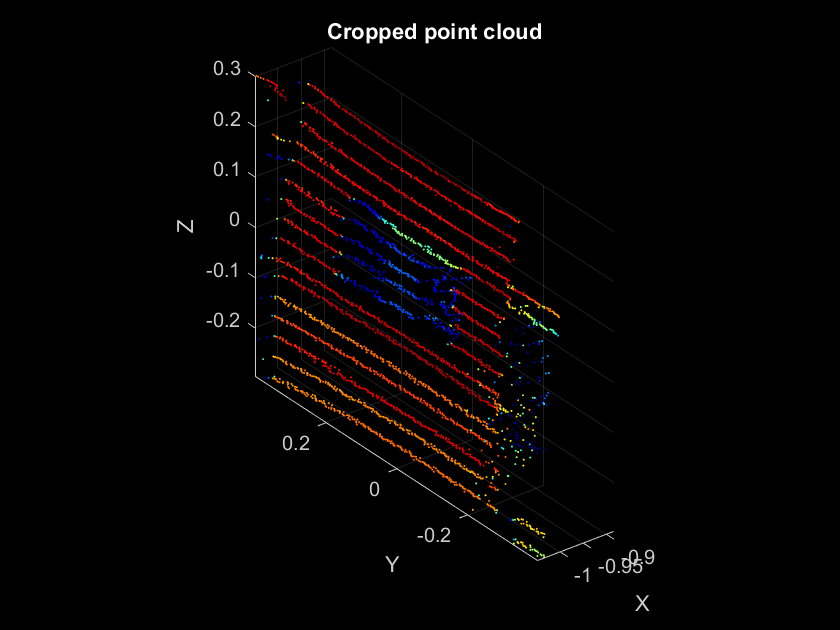

%roi = [-0.5 0 1 1.5 -0.5 0.5];
roi =[-1.05 0 -0.4 0.4 -1 1];
x=[-1.05 0];
y=[-0.4 0.4];
z=[-1 1];
indices = findPointsInROI(ptCloudObj,roi);
croppedCloud = select(ptCloudObj,indices);
figure
pcshow(croppedCloud);
xlabel("X");
ylabel("Y");
zlabel("Z");
title("Cropped point cloud")

## Segmenting

% minDistance = 0.3;
% [labels,numClusters] = pcsegdist(croppedCloud,minDistance);
% pcshow(croppedCloud.Location,labels)
% colormap(hsv(numClusters))
% title('Point Cloud Clusters')

## Downsampling

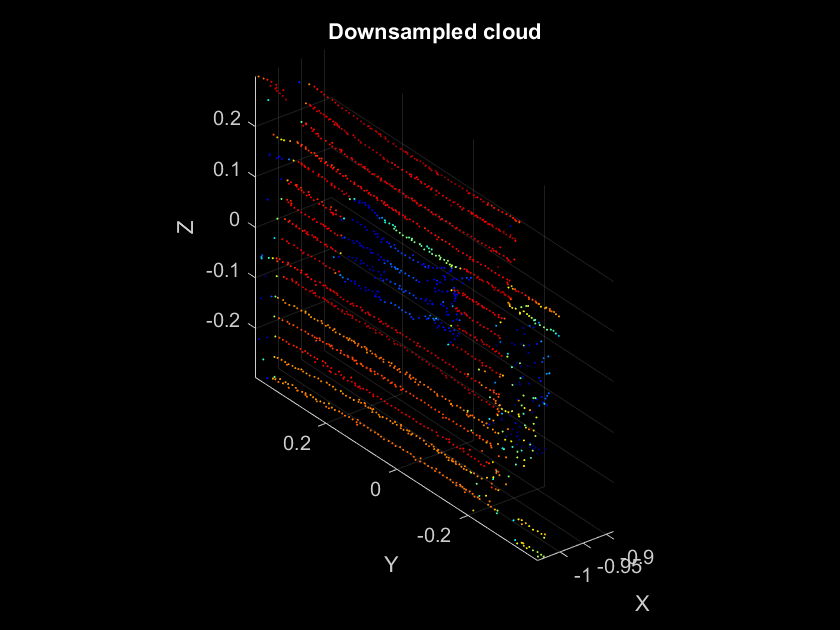

gridStep = 0.01;
ptCloudDown = pcdownsample(croppedCloud,'gridAverage',gridStep);
figure
pcshow(ptCloudDown);
xlabel("X");
ylabel("Y");
zlabel("Z");
title("Downsampled cloud")

## More cropping

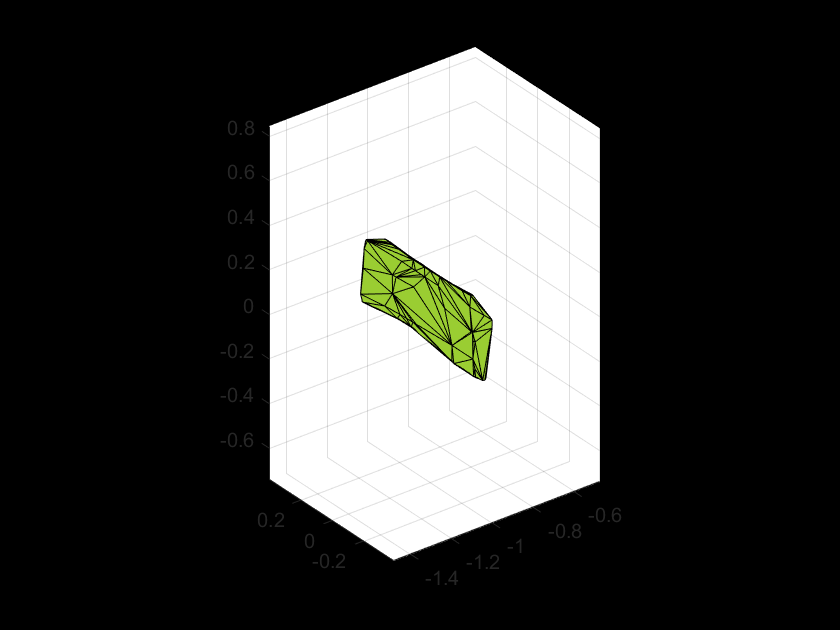

roi = [-1.05 0 -0.4 0.4 -0.1 0.2];
indices = findPointsInROI(ptCloudDown,roi);
MorecroppedCloud = select(ptCloudDown,indices);

% referenceVector = [1,0,0];
% maxDistance = 0.2;
% maxAngularDistance = 5;
%  
% [model1,inlierIndices,outlierIndices] = pcfitplane(croppedCloud,maxDistance,referenceVector,maxAngularDistance);
% plane1 = select(croppedCloud,inlierIndices);
% remainPtCloud = select(croppedCloud,outlierIndices);
% pcshow(plane1);

shp = alphaShape(double(MorecroppedCloud.Location(:,1)),double(MorecroppedCloud.Location(:,2)),double(MorecroppedCloud.Location(:,3)),1);
plot(shp)

## Separate board from tiles using intensity value

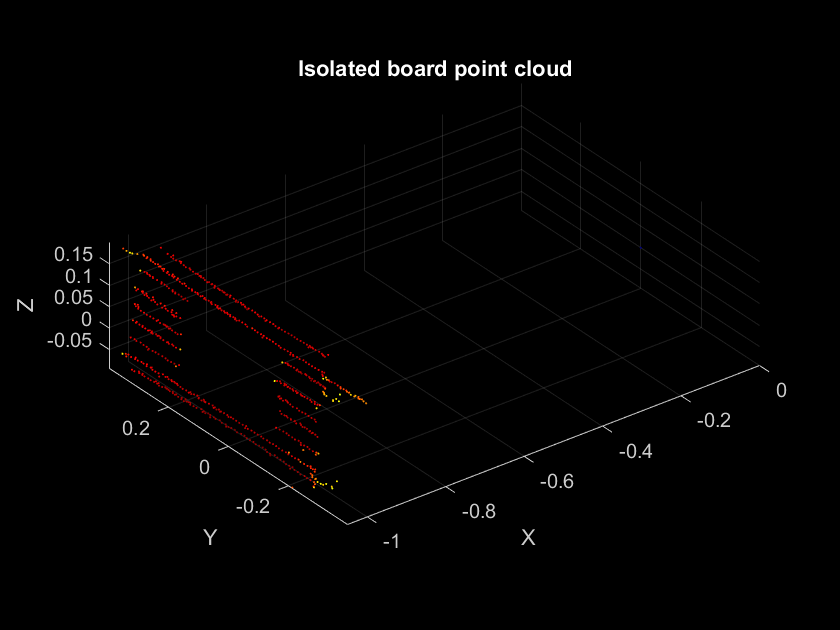

%croppedCloud=MorecroppedCloud;
n = MorecroppedCloud.Count;
board_intensity = MorecroppedCloud.Intensity;
tile_intensity = MorecroppedCloud.Intensity;

board_points = MorecroppedCloud.Location;
tile_points = MorecroppedCloud.Location;

counter = 0;
for i = 1:length(board_intensity)
    if (MorecroppedCloud.Intensity(i) < 60)
        board_intensity(i,1)=0;
        %board_points(i,:)=[0,0,0];
         board_intensity(i,1) =0;
         board_points(i,1)=0;
         board_points(i,2)=0;
         board_points(i,3)=0;
     else
         tile_intensity(i,1) =0;
         tile_points(i,1)=0;
         tile_points(i,2)=0;
         tile_points(i,3)=0;
    end

end

cleaned_intensity = board_intensity;
for i=1:n
    if (board_intensity(i,1)==0)
        %cleaned_intensity(i,1)=[]
    end
end

player = pcplayer(x,y,z);
while isOpen(player)
    view(player,board_points,board_intensity);
end

pcshow(board_points,board_intensity);
xlabel("X");
ylabel("Y");
zlabel("Z");
title("Isolated board point cloud")

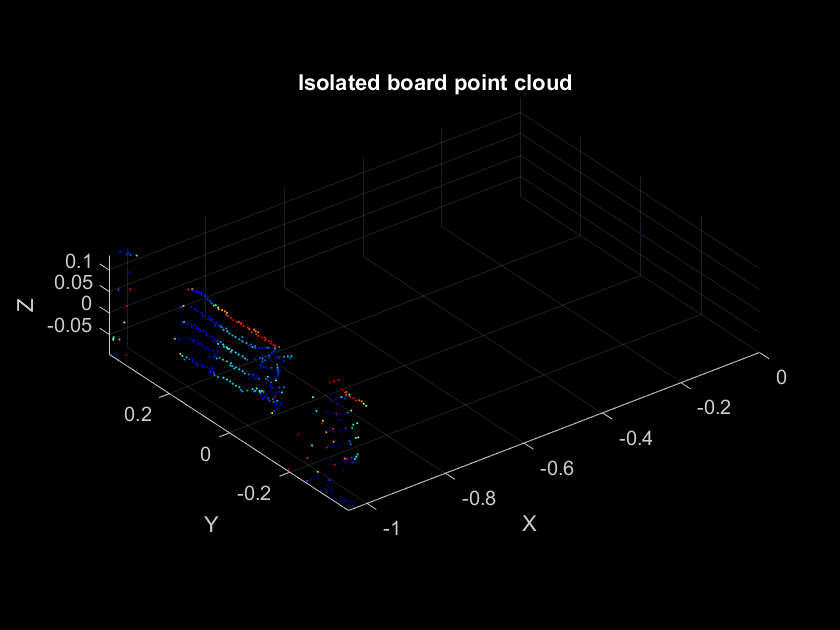

pcshow(tile_points,tile_intensity);
xlabel("X");
ylabel("Y");
zlabel("Z");
title("Isolated board point cloud")


%surf(board_points, board_intensity);
% player2 = pcplayer(x,y,z);
% while(isOpen(player2))
%     view(player,tile_points,tile_intensity);
% end

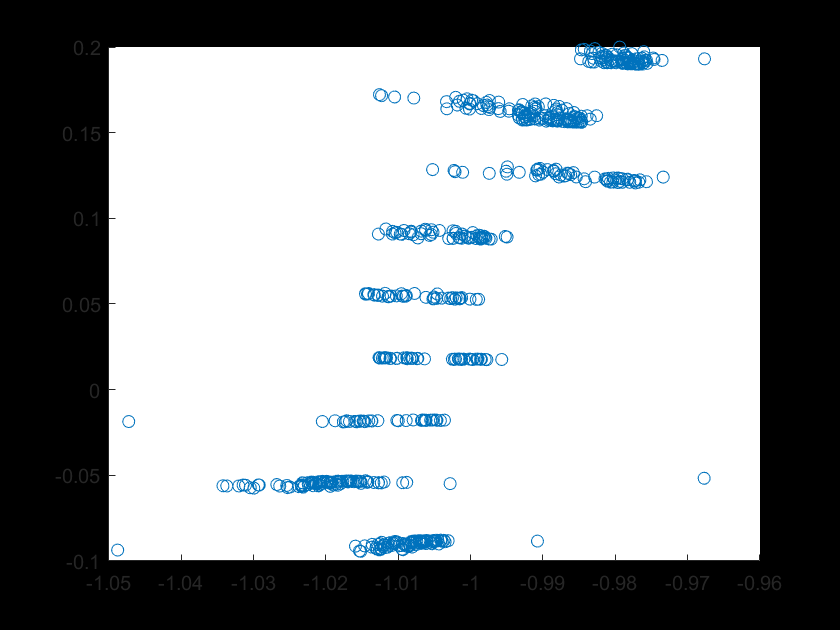

%filter board non-zero
xdata = double(board_points(:,1));
ydata = double(board_points(:,2));
zdata = double(board_points(:,3));

ind_xdata = find(xdata);
new_xdata = xdata(ind_xdata);

ind_ydata = find(ydata);
new_ydata = ydata(ind_ydata);

ind_zdata = find(zdata);
new_zdata = zdata(ind_zdata);

%filter tile non-zero
xtiles = double(tile_points(:,1));
ytiles = double(tile_points(:,2));
ztiles = double(tile_points(:,3));

ind_xtiles = find(xtiles);
ind_ytiles = find(ytiles);
ind_ztiles = find(ztiles);

new_xtiles = xtiles(ind_xtiles);
new_ytiles = ytiles(ind_ytiles);
new_ztiles = ztiles(ind_ztiles);


% zdata = find(zdata);
%surf(new_xdata, new_ydata, new_zdata);
scatter(new_xdata,new_zdata);
title("My scatter");

board_points(3)=round(board_points(3),2);

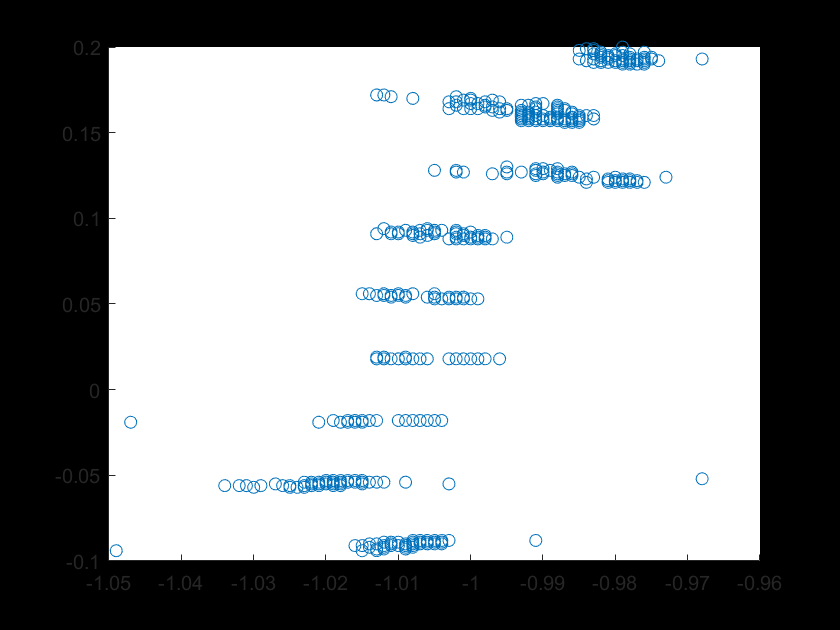

%Rounded
zdata_rounded = round(new_zdata,3);
xdata_rounded = round(new_xdata,3);
ydata_rounded = round(new_ydata,3);
uni = unique(zdata_rounded);
dim = length(zdata_rounded);
scatter((xdata_rounded), (zdata_rounded));

% adjusted_board = cell(dim,3);
% adjusted_board(:,1)=(new_xdata);
% adjusted_board(2)=new_ydata;
% adjusted_board(3)=zdata_rounded;
% pcshow(adjusted_board);
%empty_sheet = {};
%board_points(3) = zdata_rounded;
%zdata_rounded = cellfun(@(x)round(x,2),new_zdata);


Planee

% [x y] = meshgrid(-1:0.1:1); % Generate x and y data
% z = -1/C*(A*x + B*y + D); % Solve for z data
% surf(x,y,z) %Plot the surface

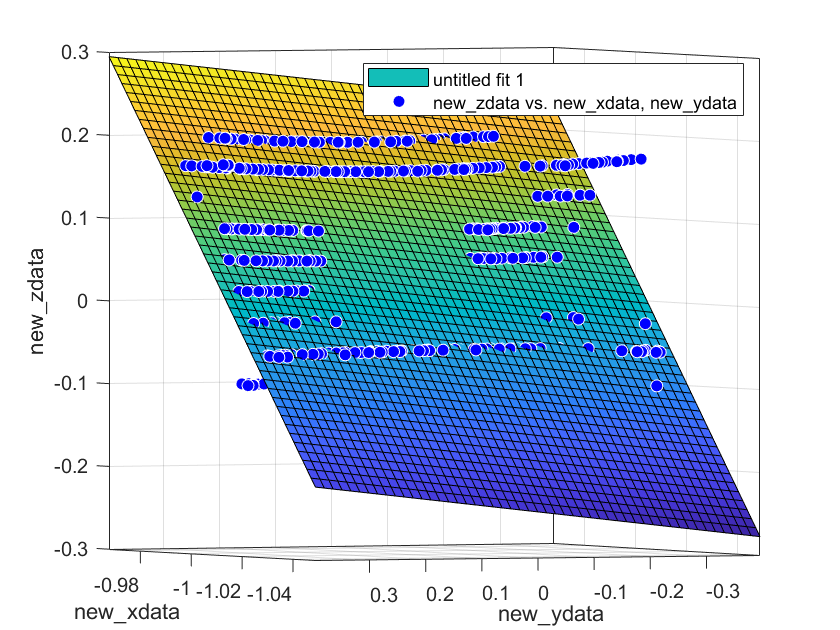

%CREATEFIT(NEW_XDATA,NEW_YDATA,NEW_ZDATA)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : new_xdata
%      Y Input : new_ydata
%      Z Output: new_zdata
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 22-Oct-2021 14:20:28


%% Fit: 'untitled fit 1'.
[xData, yData, zData] = prepareSurfaceData( new_xdata, new_ydata, new_zdata );

% Set up fittype and options.
ft = fittype( 'poly11' );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Normalize = 'on';
opts.Robust = 'LAR';

% Fit model to data.
[fitresult, gof] = fit( [xData, yData], zData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, [xData, yData], zData );
legend( h, 'untitled fit 1', 'new_zdata vs. new_xdata, new_ydata', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'new_xdata', 'Interpreter', 'none' );
ylabel( 'new_ydata', 'Interpreter', 'none' );
zlabel( 'new_zdata', 'Interpreter', 'none' );
grid on
view( -114.9, 1.5 );


coeffs = coeffnames(fitresult);
planeFormula = formula(fitresult);
coefficientValues = coeffvalues(fitresult)

coefficientValues =     0.0624    0.0906    0.0182


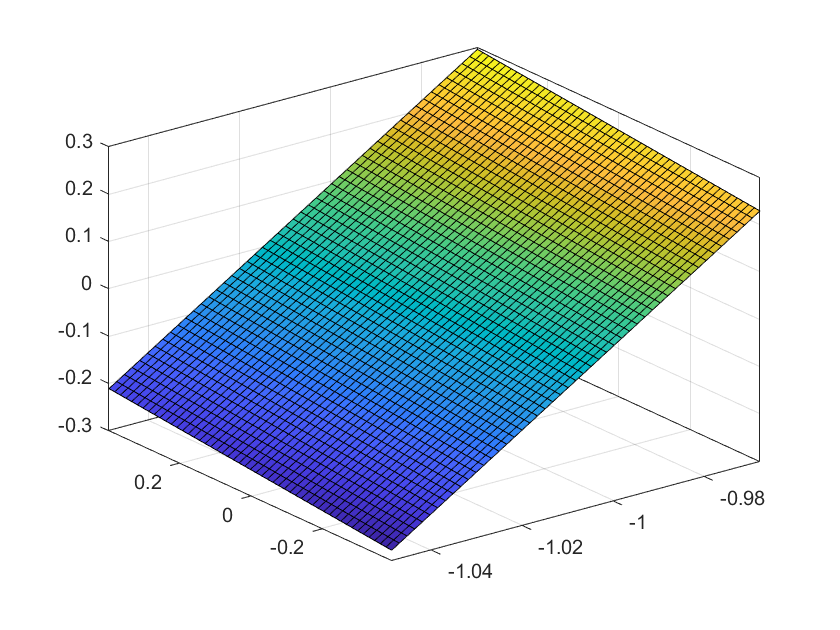

p0=coefficientValues(1);
p1=coefficientValues(2);
p2=coefficientValues(3);


plot(fitresult);

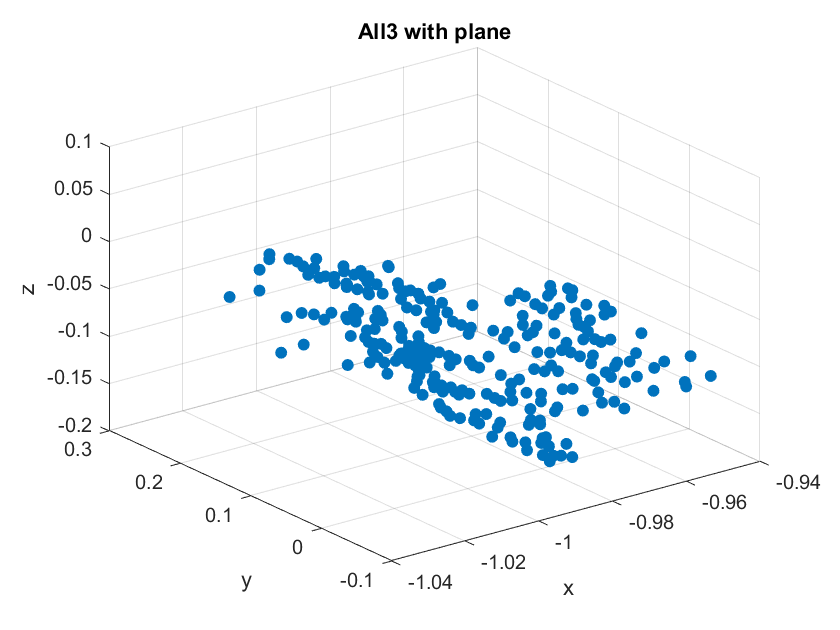

%preprocessing of tile_points: unique values

%for each point (xyz) - calculate plane
%z=p0 + p1*x + p2*y
%0= -z +p1*x + p2*y + p0


%A=2, B=−2, C=5, D=8. From the point P, we substitute x1=4, y1=−4, and z1=3
% p0=8;
% p1=2;
% p2=-2;
% 
% xpoint = 4;
% ypoint = -4;
% zpoint =3;
tile_distances = new_xtiles;

for i = 1:length(new_xtiles)
    xpoint = new_xtiles(i);
    ypoint = new_ytiles(i);
    zpoint = new_ztiles(i);
    
    denominator = sqrt(p1^2 + p2^2 + (-1)^2);
    numerator = (-1)*zpoint + p1*xpoint + p2*ypoint + p0;
    distance = numerator/denominator;
    tile_distances(i)=distance;
end

scatter3(new_xtiles, new_ytiles, tile_distances, "filled");
%axis equal;
%xlim([-50 50]);
ylim([-0.1 0.3]);
xlabel("x");
ylabel("y");
zlabel("z");
title("All3 with plane")

%pointA = {xpoint, ypoint, zpoint};
% zplane = p0 + p1*xpoint +p2*ypoint;
% planeDistance = zpoint - zplane;
% euclid = sqrt(zpoint^2 -zplane^2);
% 
% scatter3(pointA(1), pointA(2), pointA(3));

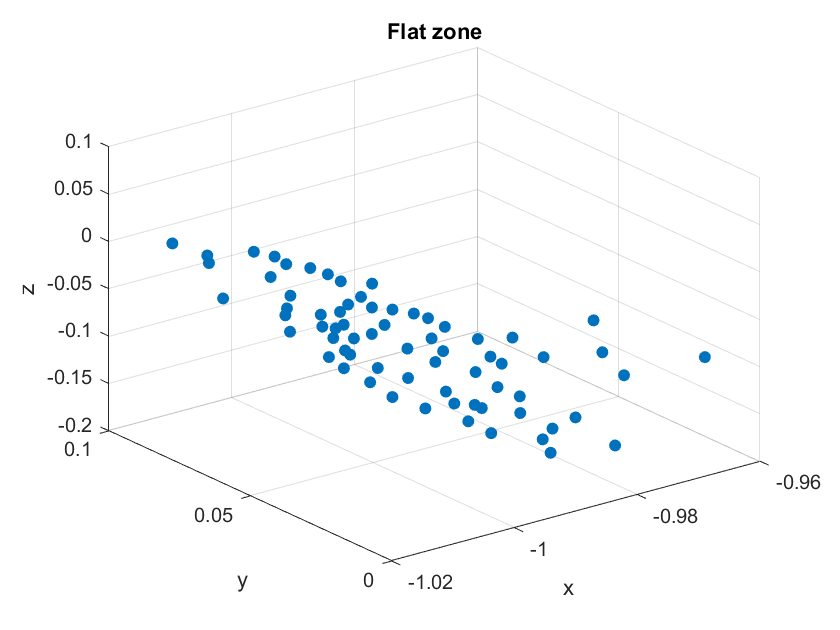

%flat zone
scatter3(new_xtiles, new_ytiles, tile_distances, "filled");
%axis equal;
%xlim([-50 50]);
ylim([0 0.1]);
xlabel("x");
ylabel("y");
zlabel("z");
title("Flat zone");

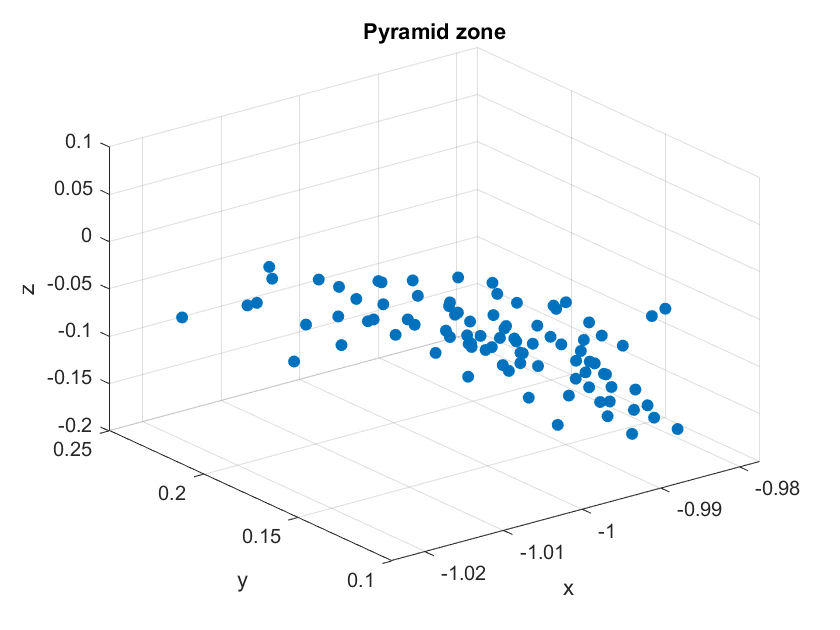


%pyramid zone
scatter3(new_xtiles, new_ytiles, tile_distances, "filled");
%axis equal;
%xlim([-50 50]);
ylim([0.1 0.25]);
xlabel("x");
ylabel("y");
zlabel("z");
title("Pyramid zone")

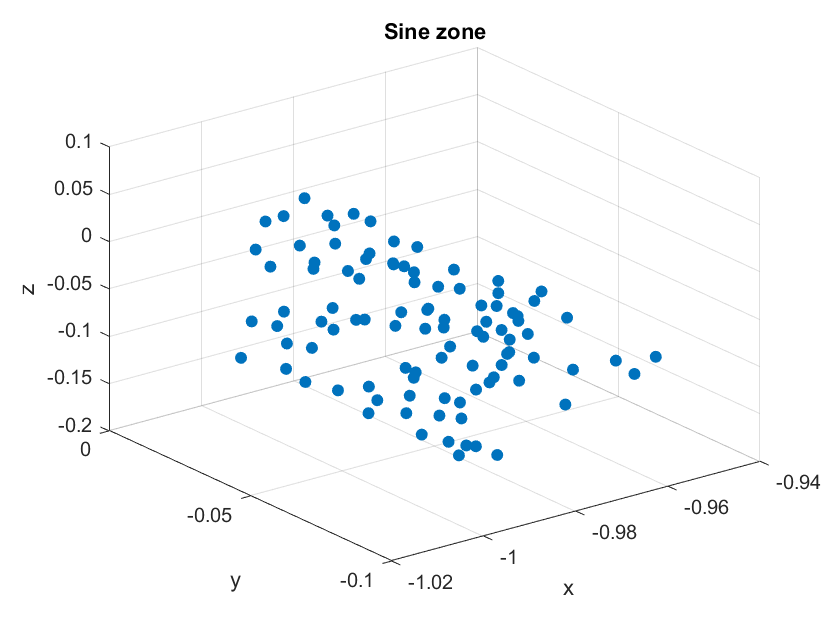


%sine zone
scatter3(new_xtiles, new_ytiles, tile_distances, "filled");
%axis equal;
%xlim([-50 50]);
ylim([-0.1 0]);
xlabel("x");
ylabel("y");
zlabel("z");
title("Sine zone");

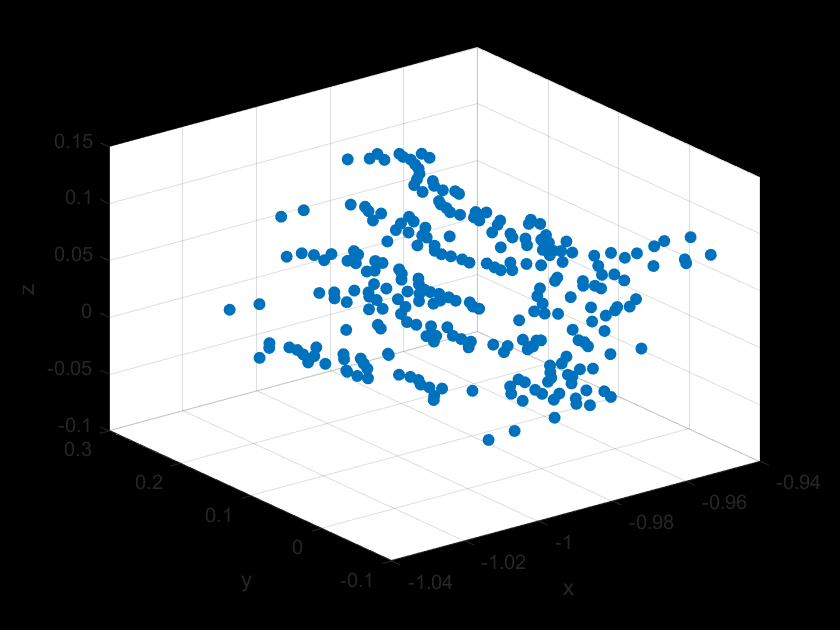

scatter3(new_xtiles, new_ytiles, new_ztiles, "filled");
%axis equal;
%xlim([-50 50]);
ylim([-0.1 0.3]);
xlabel("x");
ylabel("y");
zlabel("z");
title("All3 no plane")


tileCloud = pointCloud([new_xtiles, new_ytiles, new_ztiles])

tileCloud =   pointCloud with properties:

     Location: [372×3 double]
        Count: 372
      XLimits: [-1.0468 -0.9097]
      YLimits: [-0.3956 0.4000]
      ZLimits: [-0.0968 0.1345]
        Color: []
       Normal: []
    Intensity: []


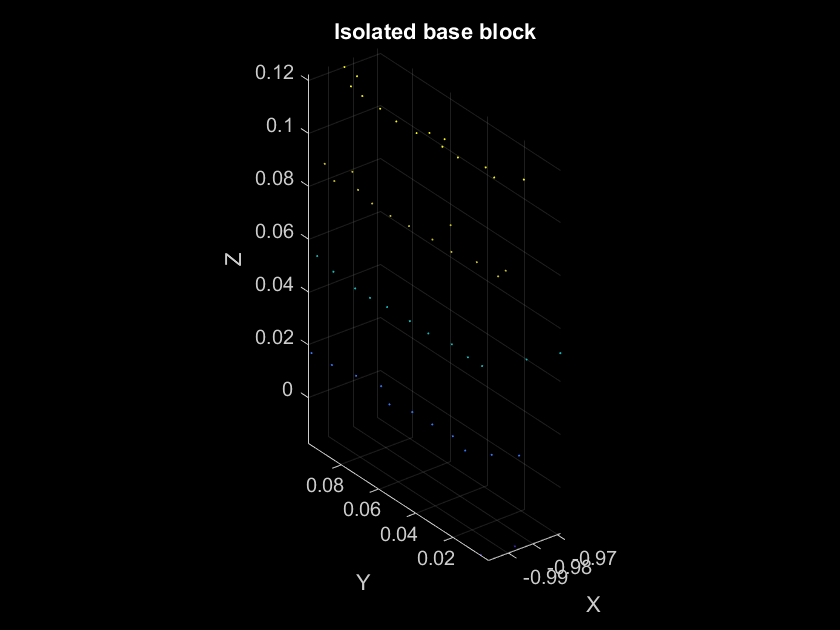


roi = [-1 1 0 0.1 -1 1];
indices = findPointsInROI(tileCloud,roi);
flatCloud = select(tileCloud,indices);

pcshow(flatCloud);
xlabel("X");
ylabel("Y");
zlabel("Z");
title("Isolated base block");

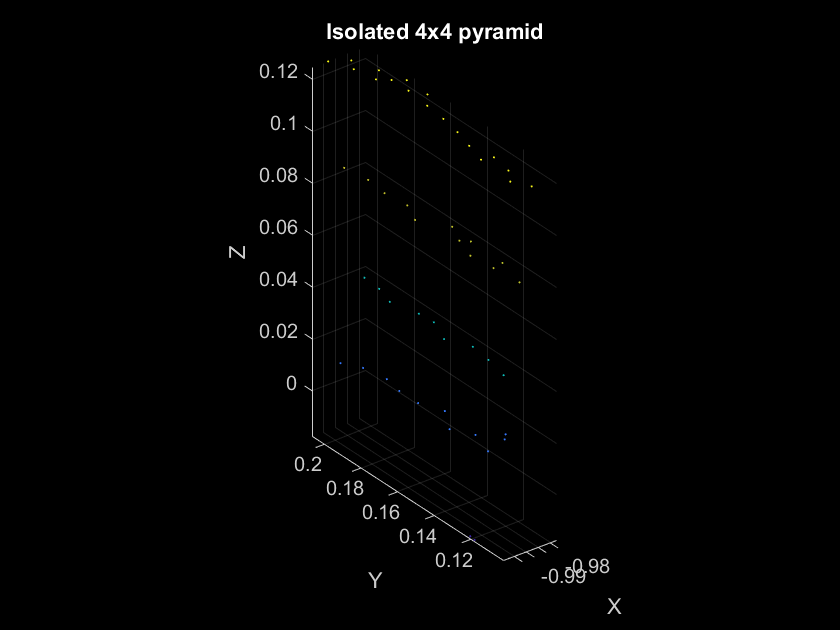

roi = [-1 1 0.1 0.25 -1 1];
indices = findPointsInROI(tileCloud,roi);
pyr = select(tileCloud,indices);
pcshow(pyr);
xlabel("X");
ylabel("Y");
zlabel("Z");
title("Isolated 4x4 pyramid");

roi = [-1 1 0 0.1 0 0.04]

roi =    -1.0000    1.0000         0    0.1000         0    0.0400


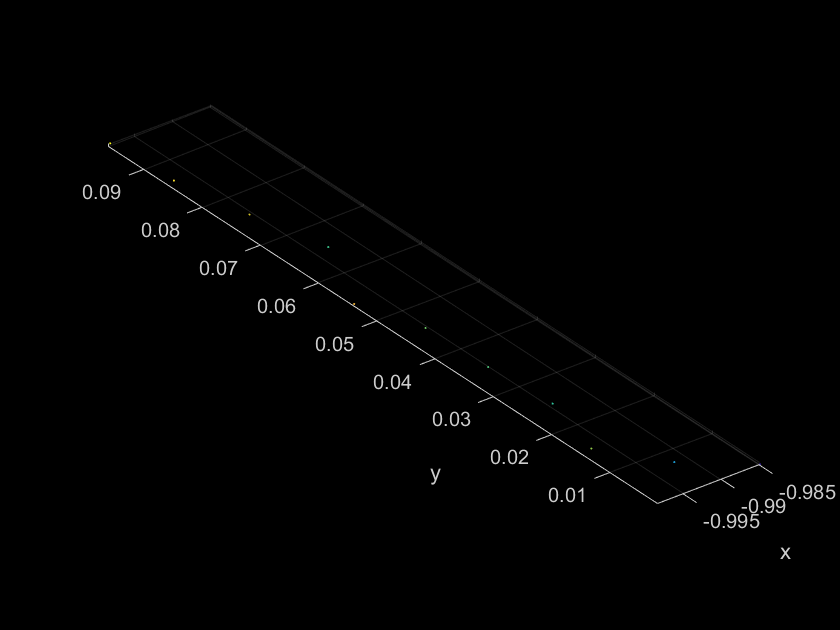

indices = findPointsInROI(flatCloud,roi);
lineACloud = select(flatCloud,indices);
pcshow(lineACloud)
xlabel("x");
ylabel("y");
zlabel("z");

linex = lineACloud.Location(:,1);
liney = lineACloud.Location(:,2);
linez = lineACloud.Location(:,3);

roi = [-1 1 -0.1 0 -1 1]

roi =    -1.0000    1.0000   -0.1000         0   -1.0000    1.0000


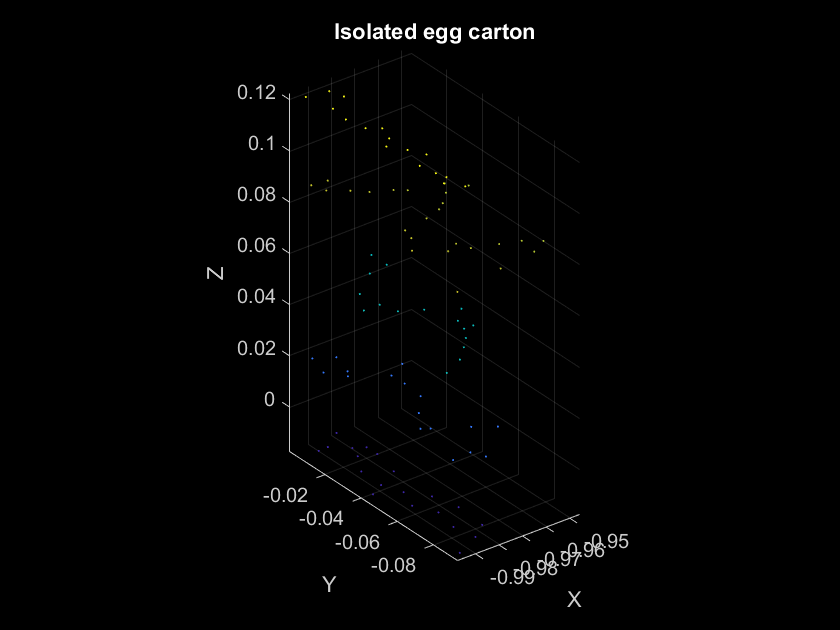

indices = findPointsInROI(tileCloud,roi);
sineCloud = select(tileCloud,indices);
pcshow(sineCloud);
xlabel("X");
ylabel("Y");
zlabel("Z");
title("Isolated egg carton");

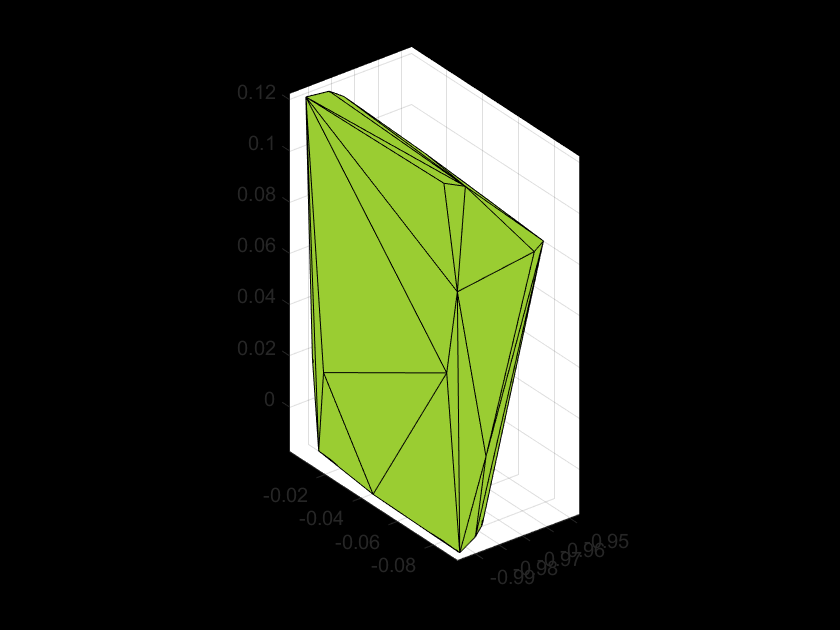


flatx = double(flatCloud.Location(:,1));
flaty = double(flatCloud.Location(:,2));
flatz = double(flatCloud.Location(:,3));

sinex = double(sineCloud.Location(:,1));
siney = double(sineCloud.Location(:,2));
sinez = double(sineCloud.Location(:,3));
sineshp = alphaShape(sinex, siney, sinez,length(sinez));
plot(sineshp);
axis equal;

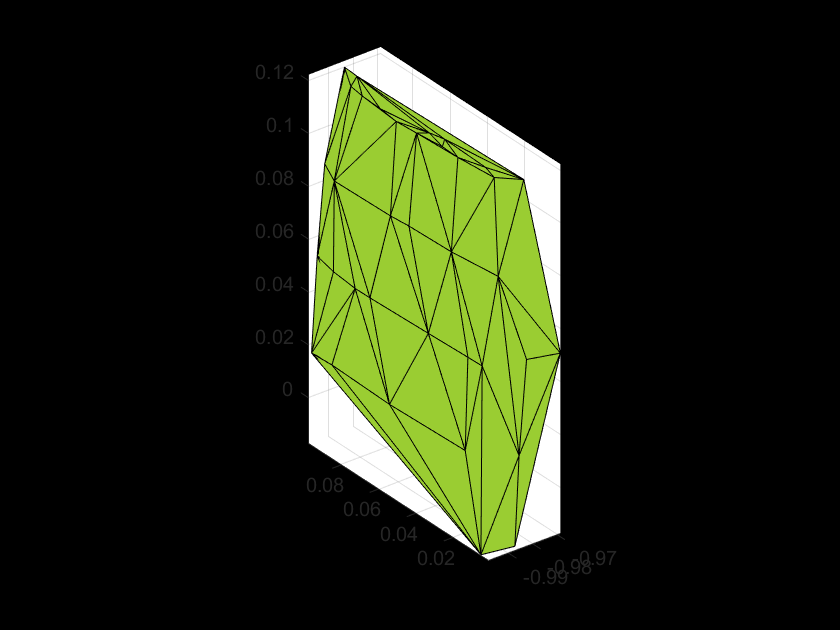

%F= scatteredInterpolant(flatx, flaty, flatz);
%mesh(flatx, flaty, flatz);
shp = alphaShape(flatx,flaty,flatz,0.25);
plot(shp)
axis equal

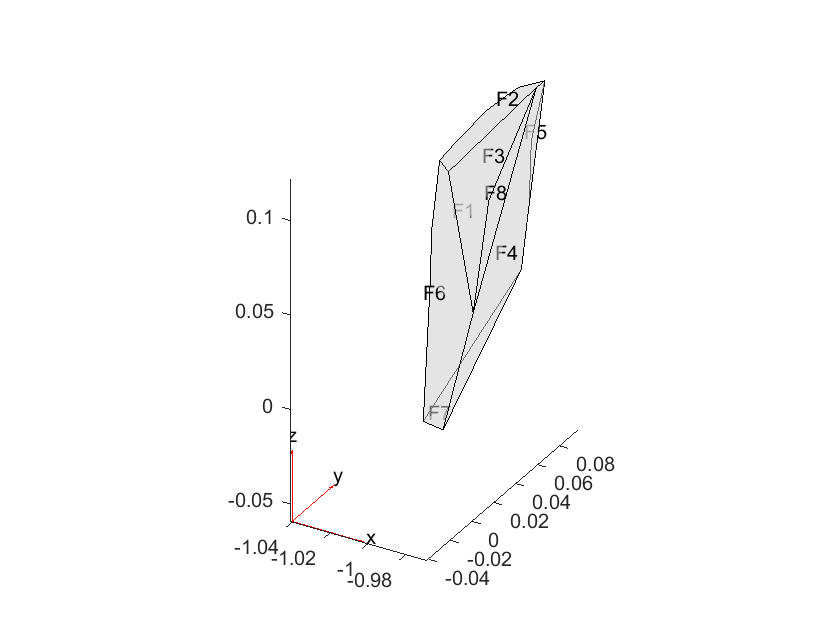

[elements,nodes] = boundaryFacets(shp);
nodes = nodes';
elements = elements';

model = createpde();
geometryFromMesh(model,nodes,elements);
pdegplot(model,'FaceLabels','on','FaceAlpha',0.5)

generateMesh(model);



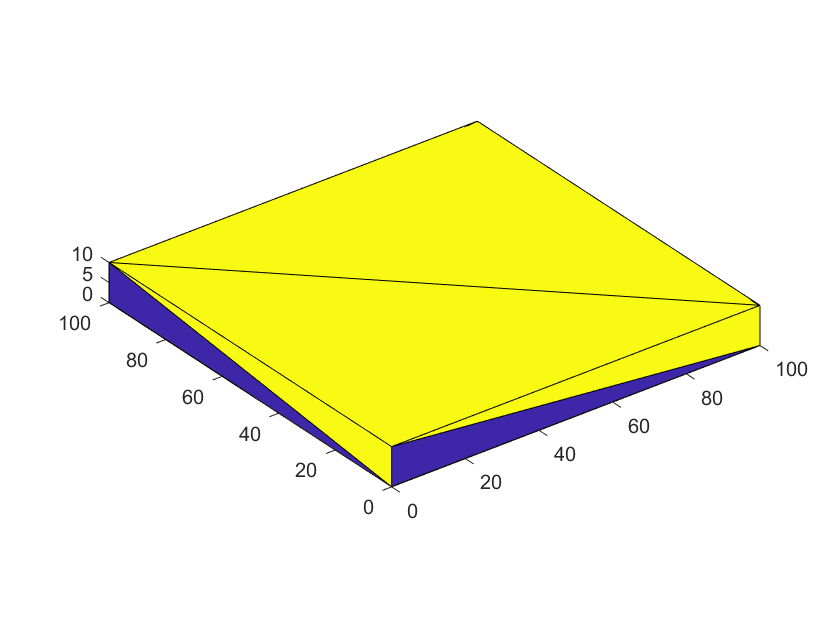

EggData = stlread('Egg-Carton.stl');
EggPoints = EggData.Points;

BlockData = stlread('Base-Block.stl');
BlockPoints = BlockData.Points;
trisurf(BlockData);
axis equal

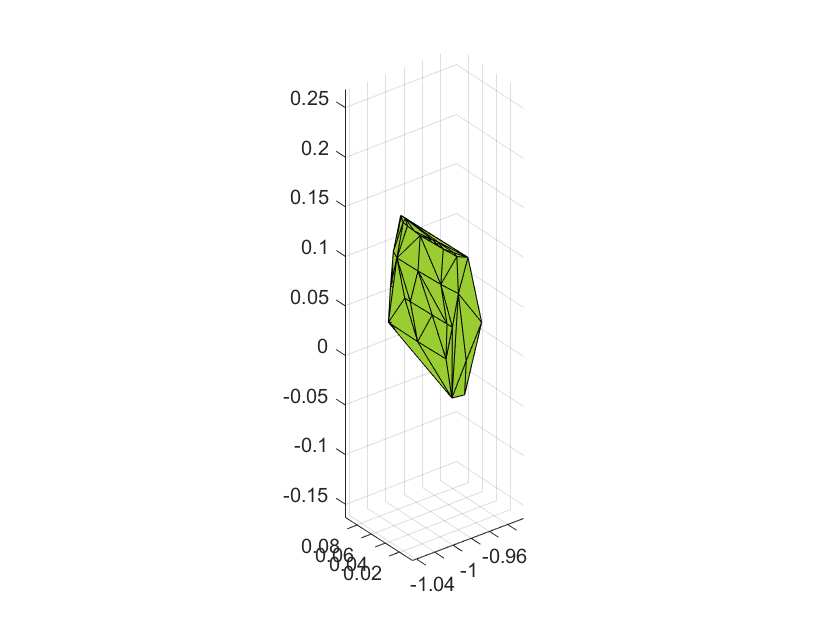



shp = alphaShape(flatx,flaty,flatz,1);
plot(shp)

%Surface values (max z for each x,y pair)
xg = linspace(min(BlockPoints(:,1)), max(BlockPoints(:,1))); % coordinates of grid
yg = linspace(min(BlockPoints(:,2)), max(BlockPoints(:,2))); % coordinates of grid
zg = linspace(min(BlockPoints(:,3)), max(BlockPoints(:,3))); % coordinates of grid

[Xg, Yg] = meshgrid(xg, yg); % X and Y grids
Z = peaks(Xg,Yg)

Z =     0.9810    2.9811    1.3434    0.0284    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.7992    2.4411    0.5422    0.0105    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

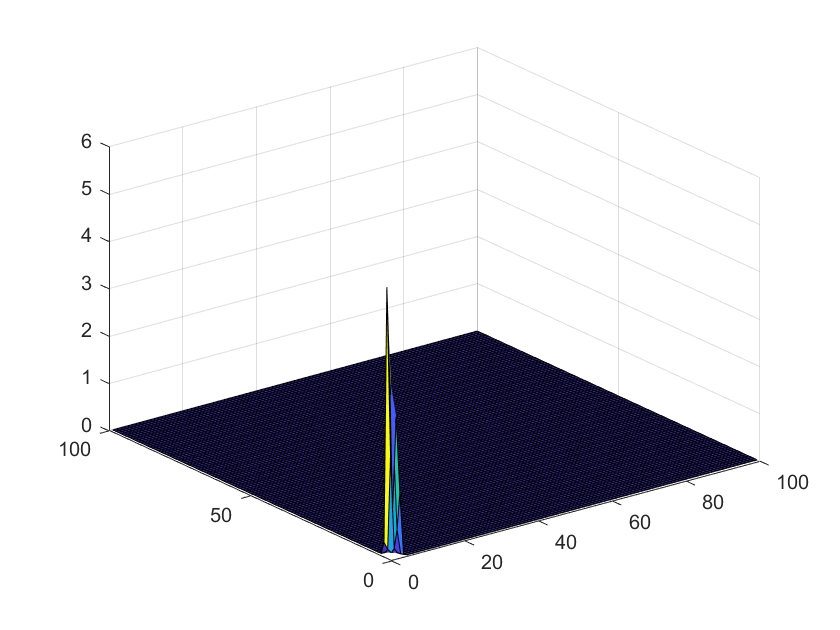


surf(Z)

%surf(Xg, Yg, Zg);

%surf(BlockPoints(:,1),BlockPoints(:,2), BlockPoints(:,3))
%arithmetic mean
non_zero_z = double(BlockPoints(:,3));
ind = find(non_zero_z);
new_nonzero_z = non_zero_z(ind);
%mean_z = cellfun(@mean, cellarray(new_nonzero_z))
mean_z = mean(new_nonzero_z)

mean_z = 10

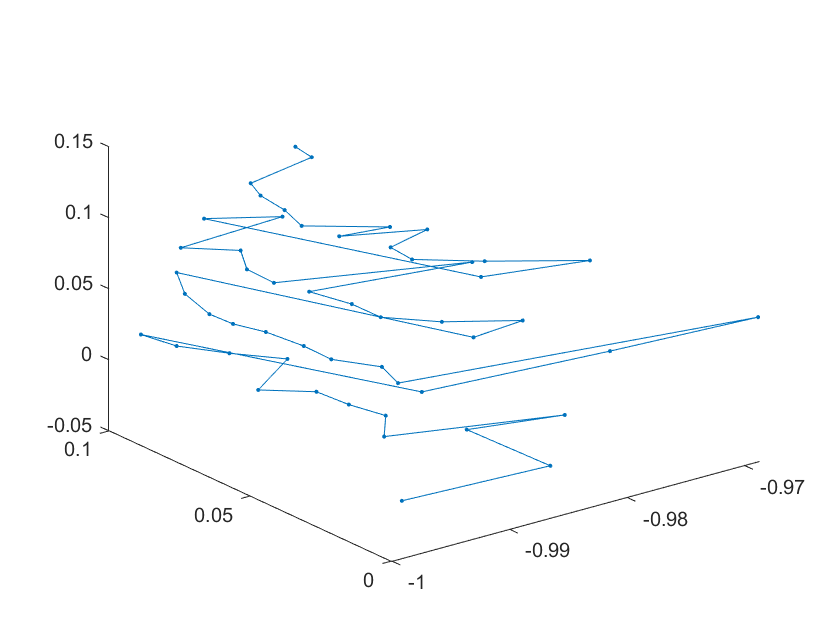

%sort by z (largest to smallest)

%for loop through all 
plot3(flatx,flaty,flatz,'.-')

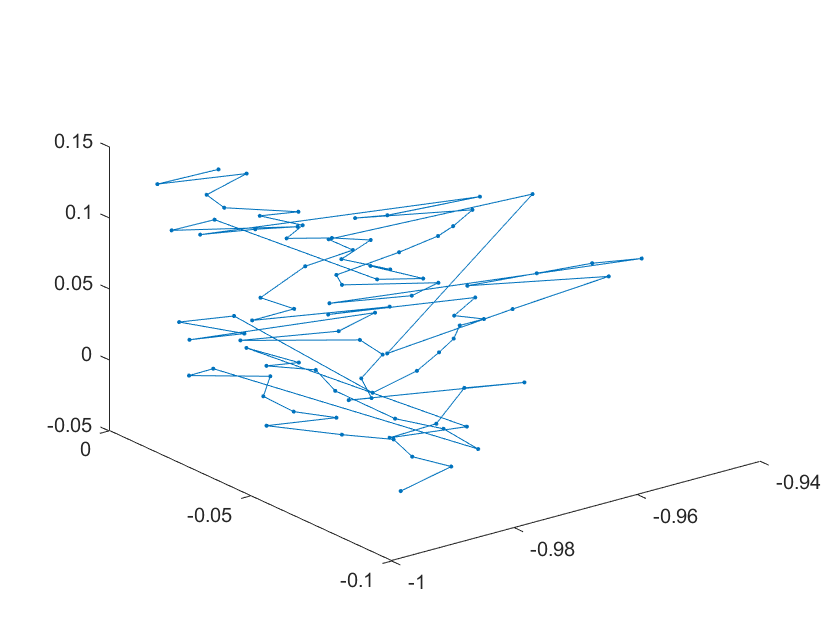

plot3(sinex, siney, sinez,'.-')

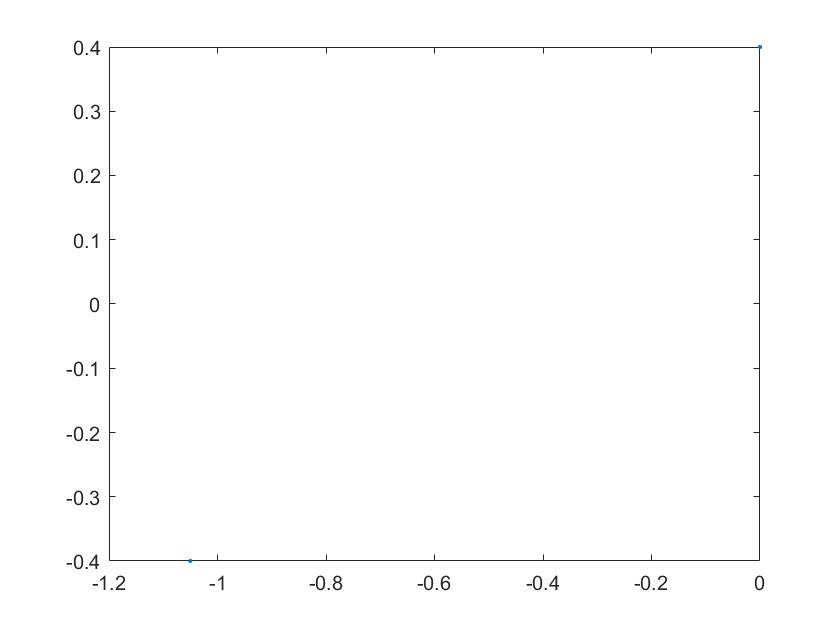

tri = delaunay(flatx,flaty);
plot(x,y,'.')

[r,c] = size(tri);
disp(r)

    94



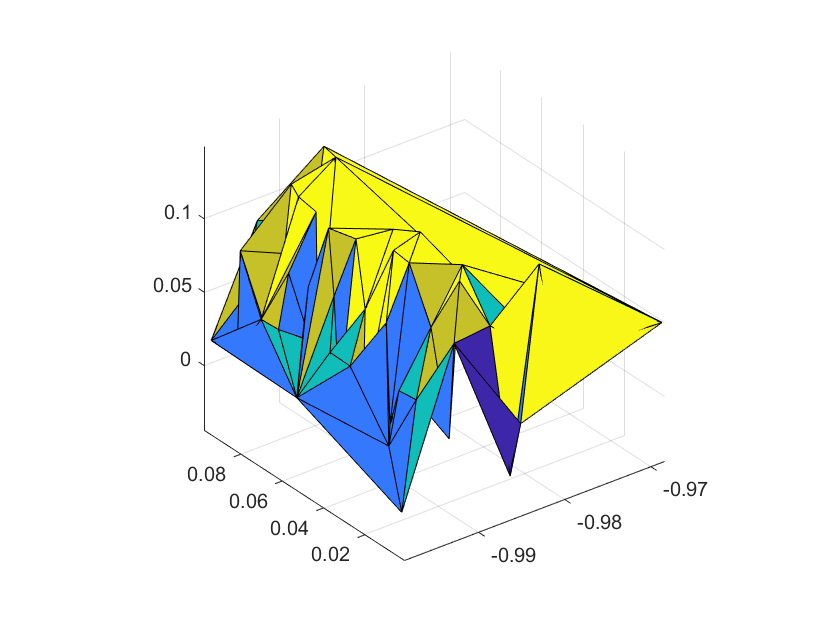

h = trisurf(tri, flatx, flaty, flatz);
axis vis3d

% X=board_points;
% N=1710;
% X_ave=mean(X,3);            % mean; line of best fit will pass through this point  
% dX=bsxfun(@minus,X,X_ave);  % residuals
% C=(dX'*dX)/(N-1);           % variance-covariance matrix of X
% [R,D]=svd(C,0); 
% 
% % Coefficient of determineation; R^2 = (explained variance)/(total variance)
% D=diag(D);
% R2=D(1)/sum(D);
% % Visualize X and line of best fit
% % -------------------------------------------------------------------------
% % End-points of a best-fit line (segment); used for visualization only 
% x=dX*R(:,1);    % project residuals on R(:,1) 
% x_min=min(x);
% x_max=max(x);
% dx=x_max-x_min;
% Xa=(x_min-0.05*dx)*R(:,1)' + X_ave;
% Xb=(x_max+0.05*dx)*R(:,1)' + X_ave;
% X_end=[Xa;Xb];
% figure('color','w')
% axis equal 
% hold on
% plot3(X_end(:,1),X_end(:,2),X_end(:,3),'-r','LineWidth',3) % best fit line 
% plot3(X(:,1),X(:,2),X(:,3),'.k','MarkerSize',13)           % simulated noisy data
% set(get(gca,'Title'),'String',sprintf('R^2 = %.3f',R2),'FontSize',25,'FontWeight','normal')
% xlabel('X','FontSize',20,'Color','k')
% ylabel('Y','FontSize',20,'Color','k')
% zlabel('Z','FontSize',20,'Color','k')
% view([20 20])
% drawnow

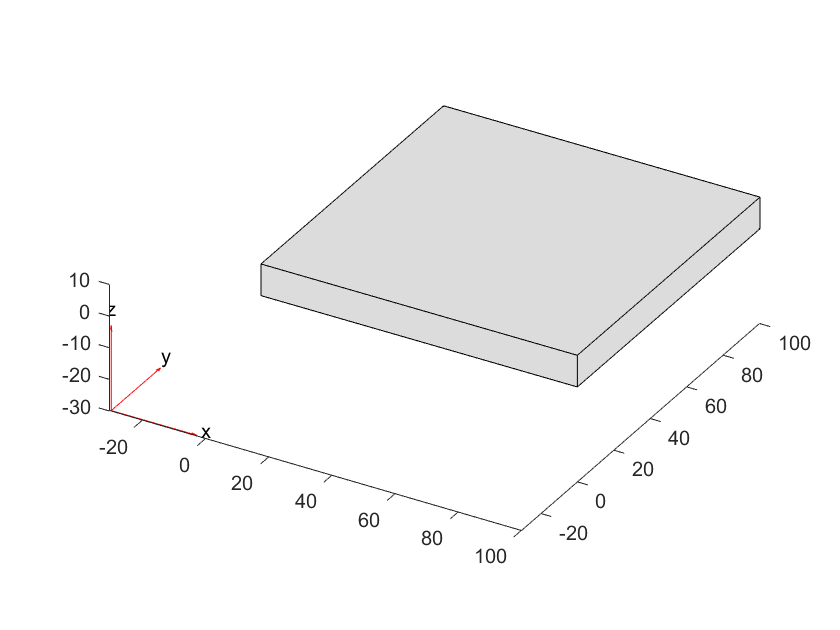

figure
gm = importGeometry('Base-Block.stl');
pdegplot(gm)

testing

outliers = [1,3,7];
elm = [1, 2, 3, 4, 5, 6, 7, 8, 9];
elm(outliers) = [];

boop={9,8,7,6,5,4,3};
boop=reshape(boop,[length(boop) 1]);


%tester = cell2mat(croppedCloud.Location);
%boop(2,2)=69;
%A = cell2mat(boop);
%test1=[];
%test1(end+1)=boop(1);
%test1(end+2)=boop(2);